    % --- Multi-Objective Genetic Algorithm Setup ---
% The goal is to find the optimal parameters for our 3rd order filters
% that meet our performance, robustness, and damping goals.

% The optimization variables are the parameters that define W1 and W3:
% x = [M_s, wb_s, M_t, wb_t]
n_vars = 4;

% Bounds for the parameters to guide the search.
lb = [1,  0.05, 1.05, 0.5];  % Lower bounds for [M_s, wb_s, M_t, wb_t]
ub = [100, 1.0,  10,  10.0]; % Upper bounds for [M_s, wb_s, M_t, wb_t]

% Set options for the genetic algorithm
options = optimoptions('gamultiobj', 'Display', 'iter', 'PopulationSize', 150);

fprintf('\n--- Running Multi-Objective Genetic Algorithm ---\n');


--- Running Multi-Objective Genetic Algorithm ---


% Run the optimizer. The objective function will return three values:
% [gamma, constraint_penalty, damping_objective]
[x_pareto, fval_pareto] = gamultiobj(@(x) multiObjectiveFunction(x, P_pitch), n_vars, [], [], [], [], lb, ub, [], options);


Multi-objective optimization:
4 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           150                 1                 1
    2           300          0.146112          0.997983
    3           450         0.0955152          0.727086
    4           600          0.144192                 1
    5           750          0.143615           1.14601
    6           900          0.233237          0.833519
    7          1050          0.113022          0.760762
    8          1200         0.0816491          0.724859
    9          1350          0.113245          0.690189
   10          1500          0.152412           0.83023
   11          1650          0.112898          0.999996
   12          1800          0.118502          0.99



% --- Process and Display Results ---
disp('Multi-objective optimization finished.');

Multi-objective optimization finished.


disp(['Found ' num2str(size(x_pareto, 1)) ' Pareto-optimal solutions.']);

Found 53 Pareto-optimal solutions.



% Find the best solution: one where all constraints are met (penalty is zero).
feasible_solutions_idx = find(fval_pareto(:, 2) < 1e-6); 

if isempty(feasible_solutions_idx)
    disp('Warning: No solution perfectly satisfied all constraints.');
    disp('Selecting the solution with the smallest constraint violation.');
    % Fallback: find the solution closest to the ideal point (gamma=0, penalty=0, damping_obj=0)
    [~, best_idx] = min(sqrt(sum(fval_pareto.^2, 2)));
else
    % From the set of feasible solutions, find the best compromise between gamma and damping.
    % We normalize both objectives and find the point closest to the ideal (0,0).
    fprintf('Found %d solutions that satisfy all constraints.\n', numel(feasible_solutions_idx));
    disp('Selecting the feasible solution with the best gamma-damping trade-off.');
    
    feasible_vals = fval_pareto(feasible_solutions_idx, [1, 3]); % Get gamma and damping_obj
    
    % Normalize the values to be between 0 and 1 for a fair comparison
    norm_vals = (feasible_vals - min(feasible_vals)) ./ (max(feasible_vals) - min(feasible_vals) + eps);
    distances = sqrt(sum(norm_vals.^2, 2)); % Distance from ideal point (0,0)
    
    [~, min_dist_idx] = min(distances);
    best_idx = feasible_solutions_idx(min_dist_idx);
end

Selecting the solution with the smallest constraint violation.



x_optimal = x_pareto(best_idx, :);


fprintf('\n--- Best Compromise Solution ---\n');


--- Best Compromise Solution ---


fprintf('Optimal Parameters [M_s, wb_s, M_t, wb_t]:\n');

Optimal Parameters [M_s, wb_s, M_t, wb_t]:


disp(x_optimal);

  39.705876541792250   0.074790924376496   2.451755062653417   2.392472792337026




% Reconstruct the optimal weighting functions for the selected solution
M_s_opt  = x_optimal(1);
wb_s_opt = x_optimal(2);
M_t_opt  = x_optimal(3);
wb_t_opt = x_optimal(4);
W1_optimal = M_s_opt * (1 / (s/wb_s_opt + 1))^2;
W3_optimal = M_t_opt * ( (s / wb_t_opt) / (s/wb_t_opt + 1) )^2;

disp('Optimal W1:');

Optimal W1:


disp(W1_optimal);

  tf with properties:

       Numerator: {[0 0 0.222102061561118]}
     Denominator: {[1 0.149581848752992 0.005593682369091]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



disp('Optimal W3:');

Optimal W3:


disp(W3_optimal);

  tf with properties:

       Numerator: {[14.033664700941136 0 0]}
     Denominator: {[5.723926062072926 27.388674737716581 32.763329564077672]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Calculate the controller and margins with the optimal weights
[K_optimal, ~, gamma_optimal] = mixsyn(P_pitch, W1_optimal, [], W3_optimal);
margins_optimal = allmargin(P_pitch * K_optimal);
CL_optimal = feedback(P_pitch*K_optimal, 1);
min_damping_optimal = min(damp(CL_optimal));

fprintf('\n--- Performance of Best Compromise Solution ---\n');


--- Performance of Best Compromise Solution ---


fprintf('Final Gamma: %f\n', gamma_optimal);

Final Gamma: 0.421579


fprintf('Minimum Damping Ratio: %f\n', min_damping_optimal);

Minimum Damping Ratio: 0.025664


if ~isempty(margins_optimal.GainMargin)
    fprintf('Gain Margins (abs): %s\n', mat2str(margins_optimal.GainMargin, 3));
end

Gain Margins (abs): [0.276 37.5]


if ~isempty(margins_optimal.PhaseMargin)
    fprintf('Phase Margin (deg): %f\n', min(margins_optimal.PhaseMargin));
end

Phase Margin (deg): 64.107645



disp('Optimal Controller K:');

Optimal Controller K:


disp(K_optimal);

  ss with properties:

                A: [8×8 double]
                B: [8×1 double]
                C: [-2.142789741123817e+03 -1.855964135260497e+04 1.285666999998252e+03 -3.892267696447540e+02 -49.373440337908967 -9.891771594540809e+03 -1.331976122390028e+04 -6.705733400430189e+02]
                D: 0
                E: []
          Offsets: []
           Scaled: 0
        StateName: {8×1 cell}
        StatePath: {8×1 cell}
        StateUnit: {8×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



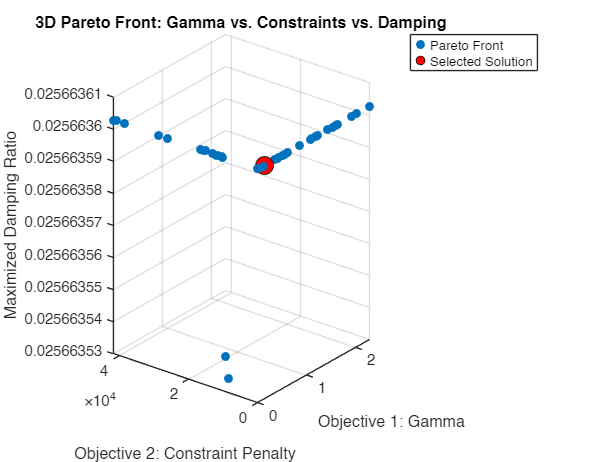


% --- Plot the Pareto Front ---
figure;
scatter3(fval_pareto(:,1), fval_pareto(:,2), 1-fval_pareto(:,3), 'filled');
hold on;
% Highlight the selected "best" solution
scatter3(fval_pareto(best_idx,1), fval_pareto(best_idx,2), 1-fval_pareto(best_idx,3), 150, 'r', 'filled', 'MarkerEdgeColor','k');
legend('Pareto Front', 'Selected Solution');
xlabel('Objective 1: Gamma');
ylabel('Objective 2: Constraint Penalty');
zlabel('Maximized Damping Ratio');
title('3D Pareto Front: Gamma vs. Constraints vs. Damping');
grid on;
view(3);



% --- Multi-Objective Function Definition ---
function objectives = multiObjectiveFunction(x, P_pitch)
    s = tf('s');
    M_s  = x(1); wb_s = x(2); M_t  = x(3); wb_t = x(4);
    W1 = M_s * (1 / (s/wb_s + 1))^3;
    W3 = M_t * ( (s / wb_t) / (s/wb_t + 1) )^3;

    try
        [K, CL, gamma] = mixsyn(P_pitch, W1, [], W3);
    catch
        objectives = [1e12, 1e12, 1e12]; 
        return;
    end
    
    margins = allmargin(P_pitch * K);
    all_gms = margins.GainMargin;
    min_pm = min(margins.PhaseMargin);
    
    % --- Check for Instability and calculate damping ---
    if ~isstable(CL) || isempty(min_pm) || isnan(min_pm)
        min_damping = 0; % Unstable system has zero effective damping
    else
        min_damping = min(damp(CL));
    end

    % --- Define the Three Objectives ---
    
    % Objective 1: Minimize gamma.
    obj1_gamma = gamma;
    
    % Objective 2: Minimize constraint violations.
    constraint_penalty = 0;
    target_gm = 1.0;
    if ~isempty(all_gms)
        for i = 1:numel(all_gms)
            if all_gms(i) < target_gm
                constraint_penalty = constraint_penalty + (target_gm - all_gms(i))^2;
            end
        end
    else % Handle case where margins can't be computed
        constraint_penalty = constraint_penalty + 100;
    end
    
    target_pm = 30.0;
    if min_pm < target_pm
        constraint_penalty = constraint_penalty + (target_pm - min_pm)^2;
    end
    
    target_gamma = 10.0;
    if gamma > target_gamma
        constraint_penalty = constraint_penalty + (gamma - target_gamma)^2;
    end
    
    % Objective 3: Maximize damping ratio (by minimizing 1 - damping).
    % Ensure damping is capped at 1 for the calculation to avoid negative objectives.
    obj3_damping = 1 - min(min_damping, 1.0);

    objectives = [obj1_gamma, constraint_penalty, obj3_damping];
end

hold off

Function 'multiObjectiveFunction' has already been declared within this scope.

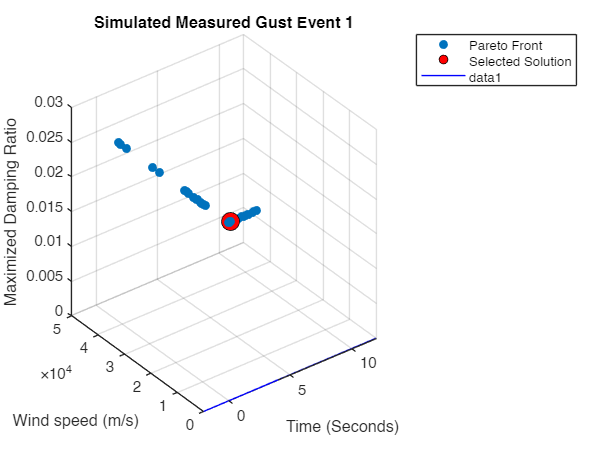

[t, wind_speed] = generate_gust_event1();
plot(t, wind_speed, 'b');

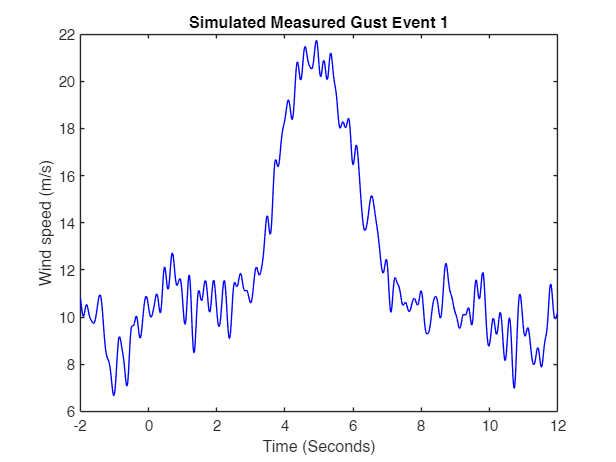

xlabel('Time (Seconds)');
ylabel('Wind speed (m/s)');
title('Simulated Measured Gust Event 1');
function [t, wind_speed] = generate_gust_event1()
    % Time vector

    dt = 0.01;
    t = -2:dt:12;
    n = length(t);
    
    % Base gust shape (like IEC EOG model)
    gust_peak = 20;  % Peak wind speed
    gust_duration = 3;  % Duration over which gust occurs
    gust_center = 5;  % Center time of gust
    
    base_gust = 10 + (gust_peak - 10) * exp(-((t - gust_center).^2) / (2 * (gust_duration / 2.5)^2));
    
    % Add high-frequency turbulence using filtered noise
    rng('shuffle');  % For variability
    turbulence = 3 * randn(1, n);
    turbulence = lowpass(turbulence, 0.5, 1/dt);  % Smooth it a bit
    
    % Add mid-frequency gustiness
    mid_freq = sin(2 * pi * 0.25 * t) + 0.5 * sin(2 * pi * 0.5 * t + pi/4);
    
    % Combine all components
    wind_speed = base_gust + turbulence + mid_freq;
    
    % Optional: Clip values to be physically reasonable
    wind_speed(wind_speed < 0) = 0;
end

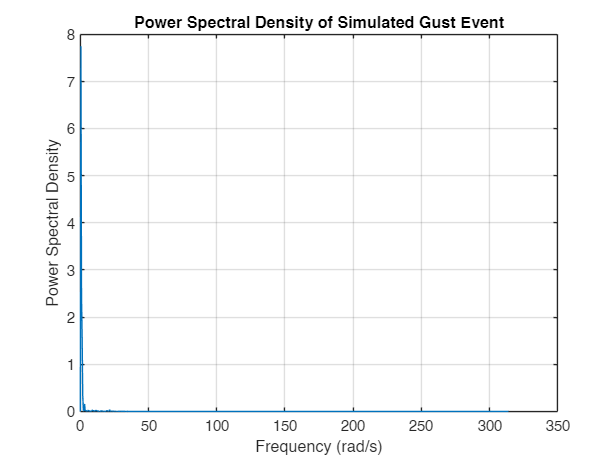

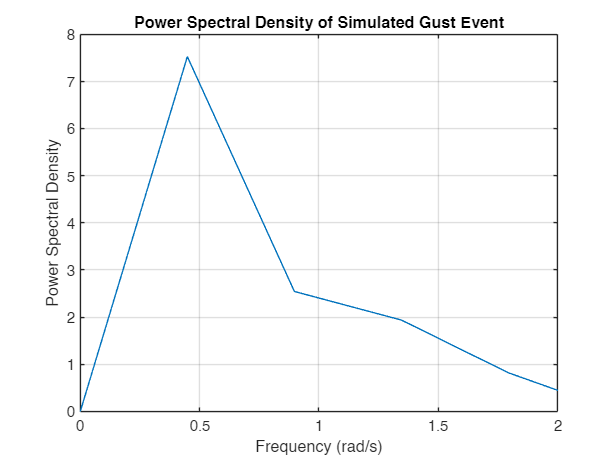

gust_psd_rad_s

function gust_psd_rad_s()
    % Generate gust signal
    [t, wind_speed] = generate_gust_event1();
    dt = t(2) - t(1);       % Sampling interval
    Fs = 1/dt;              % Sampling frequency in Hz
    N = length(t);          % Number of points

    % Remove mean to avoid DC component dominating
    wind_speed = wind_speed - mean(wind_speed);

    % FFT
    Y = fft(wind_speed);
    P2 = abs(Y/N).^2;       % Two-sided power spectrum
    P1 = P2(1:floor(N/2)+1); % Single-sided
    P1(2:end-1) = 2*P1(2:end-1);

    % Frequency vector in rad/s
    f_Hz = (0:floor(N/2)) * (Fs/N);
    omega = 2 * pi * f_Hz;  % Convert Hz to rad/s

    % Plot
    hold off
    figure;
    plot(omega, P1);
    xlabel('Frequency (rad/s)');
    xlim([0, 2])
    ylabel('Power Spectral Density');
    title('Power Spectral Density of Simulated Gust Event');
    grid on;
end